## Stat exam prep & general help

- notes

# Week 1

clc; clear;

% data = xlsread("Data_M4STI1_2017E.xlsx", 'K:L');
data = readtable("Data_M4STI1_2017E.xlsx")


opg3_brembo = rmmissing(table2array(data(:,"Opg3_Brembo")));
opg3_cl = rmmissing(table2array(data(:, "Opg3_CI")));

deskripts(opg3_brembo',"Brembo")
deskripts(opg3_cl',"Brembo")


## Visuals

rng(2)
randmat = [2.2:0.1:3.5, 3.6, 4.2:0.1:5.2];

stemleafplot(randmat, -1)

figure
histogram(randmat, 2:1:6);

title("Histo")


### Histo med categorical

figure

cat = categorical(floor(randmat), [2, 3, 4, 5], ["Starts with 2","Starts with 3","Starts with 4","Starts with 5"]);

histogram(cat)
ylim([0,10])


## Boxplots

figure("Visible","on")
boxplot([randmat',randmat'])

% Brembo og Cl
figure("Visible","on")
boxplot([opg3_cl, opg3_brembo],["Cl","Brembo"],"Notch","on")
hold on
yline(h(1))
yline(h(2))
hold off


% normrnd data
n1 = normrnd(5,1,100,1);
n2 = normrnd(6,1,100,1);

[d,g,h,j]=ztest(n1, 5,1,"Alpha",0.05);

figure
boxplot([n1,n2], ["Jeff","John"],"Notch","on")

hold on
yline(h(1))
yline(h(2))
hold off




# Week 2

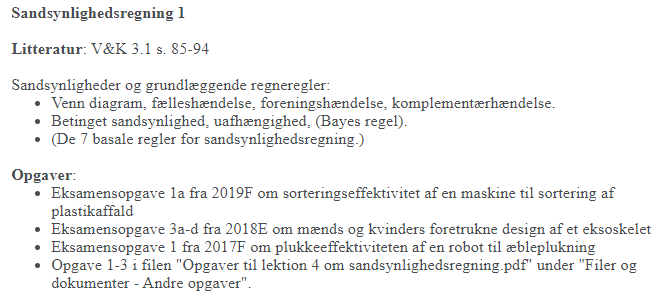

## Sorteringseffektivitet

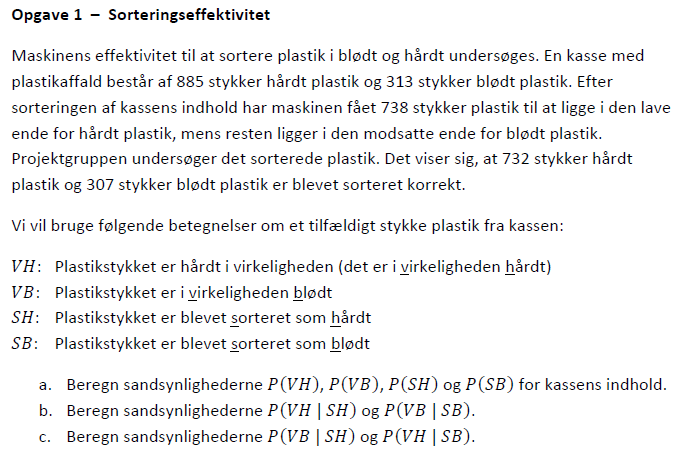

clc; clear;

% Faktiske data
n_hard = 885; % Antal hårde plast stykker
n_soft = 313; % Antal bløde plast stykker
n_tot = n_hard + n_soft; % Total population af plast

% Maskinens sortering
m_hard = 738;              % Maskinen har sorteret så mange hårde
m_soft = n_tot - m_hard;   % Maskinen har sorteret så mange bløde

% Antal der er sorteret korrekt
k_hard = 732;
k_soft = 307;

%---------------- Udregninger ----------------%

% Sandsynligheder til a)
pVH = n_hard/n_tot        % Hvor mange der faktisk er hårde, over hvor mange der er sorteret som hårde
pVB = n_soft/n_tot        % Hvor mange der faktisk er bløde, over hvor mange der er sorteret som bløde

pSH = m_hard/n_tot        % Hvor mange der er sorteret som hårde, ud fra den totale population
pSB = m_soft/n_tot        % Hvor mange der er sorteret som bløde, ud fra den totale population

% Sandsynligheder til b)
pVH_SH = k_hard/m_hard    % Hvor mange der faktisk er hårde, ift hvor mange der er sorteret som hårde
pVB_SB = k_soft/m_soft    % Hvor mange der faktisk er bløde, ift hvor mange der er sorteret som bløde

% Sandsynligheder til c)
pVB_SH = 1 - pVH_SH       % I virkeligheden blødt, men sorteret som hårdt
pVH_SB = 1 - pVB_SB       % I virkeligheden hårdt, men sorteret som blødt

% Opgave d
pSH_ny = 0.78
pSB_ny = 1 - pSH_ny

% Sandsynligheden for at det i virkeligheden er hårdt ganget med ssh'en sorteret
% som hårdt, plus sandsynligheden for det i virkeligheden er hårdt, men
% sorteret som blødt ganget med ssh'en for sorteret som blødt
pVH_ny = pVH_SH * pSH_ny + pVH_SB * pSB_ny

% Opgave e
% Bayes regel
pSH_VH = pVH_SH * pSH_ny/pVH_ny


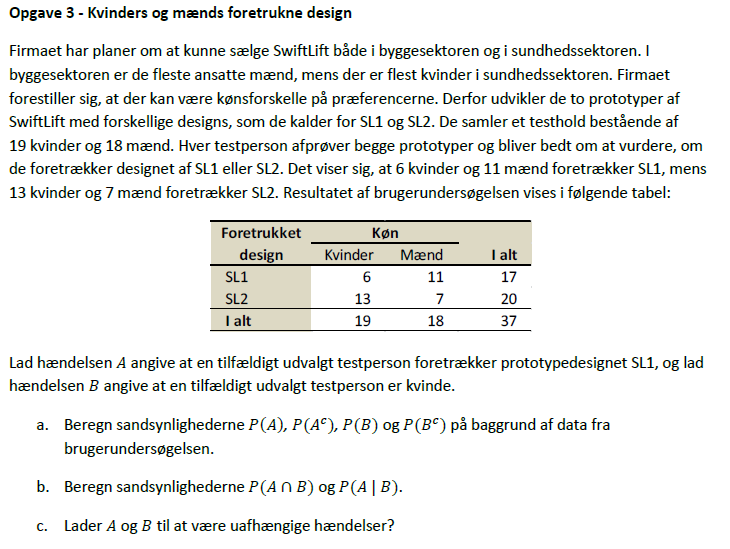

clc; clear;

% SL1 data
sl1_k = 6

sl1_k = 6

sl1_m = 11 

sl1_m = 11

sl1_tot = sl1_k + sl1_m

sl1_tot = 17


% SL2 data
sl2_k = 13

sl2_k = 13

sl2_m = 7 

sl2_m = 7

sl2_tot = sl2_k + sl2_m

sl2_tot = 20


% Populations antal
n_tot = sl1_tot + sl2_tot

n_tot = 37


%---------------------------------------------%
%---------------- Udregninger ----------------%
%---------------------------------------------%

% Opgave a)
pA = sl1_tot/n_tot

pA = 0.4595

pAc = 1-pA

pAc = 0.5405

pB = (sl1_k + sl2_k)/n_tot

pB = 0.5135

pBc = 1 - pB

pBc = 0.4865


% Opgave b)
pA_og_B = sl1_k/n_tot

pA_og_B = 0.1622

pA_hvis_B = sl1_k/sl1_tot

pA_hvis_B = 0.3529


% Opgave c)
pA == pA_hvis_B

ans = logical
   0


% Ved tjek om de 2 hændelser er ens, ses det at resultatet er 0, altså
% false, så de er afhængige

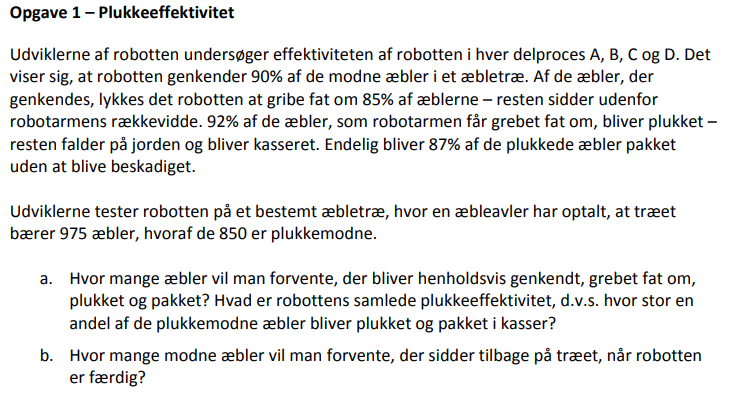

clc; clear;


pA = 0.9; pB = 0.85; pC = 0.92; pD = 0.87;

% Opgave a
n = 850; % Plukkemodne

n_genkendt = pA*n

n_genkendt = 765

n_grebet = pB * n_genkendt

n_grebet = 650.2500

n_plukket = pC * n_grebet

n_plukket = 598.2300

n_pakket = pD * n_plukket

n_pakket = 520.4601


% Opgave b
n_ikke_genkendt = (1 - pA) * n

n_ikke_genkendt = 85.0000

n_ikke_grebet = (1 - pB) * n_genkendt

n_ikke_grebet = 114.7500


n_modne_tilbage = n_ikke_genkendt + n_ikke_grebet

n_modne_tilbage = 199.7500

### Opgaver fra lektion 4

- Opgaver 1 - 3

clc; clear;




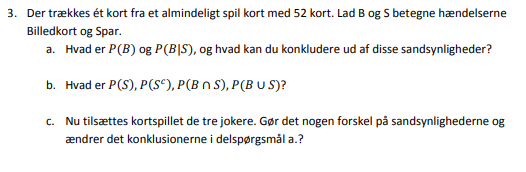

% Opgave 3
n = 52;
nbilled = 12;
nspar = 13;

%Opgave a
Pbilled = nbilled/n

Pbilled = 0.2308

Pspar = nspar/n

Pspar = 0.2500

P_billed_spar = 3/n

P_billed_spar = 0.0577

% P_billed_givet_spar = Pbilled * Pspar

P_billed_givet_spar = P_billed_spar/Pspar

P_billed_givet_spar = 0.2308


P_billed_givet_spar = (3/n)/(3/12)

P_billed_givet_spar = 0.2308

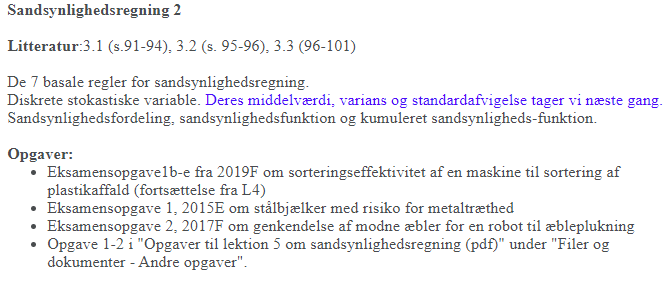

# Lektiecafe d. 21-02

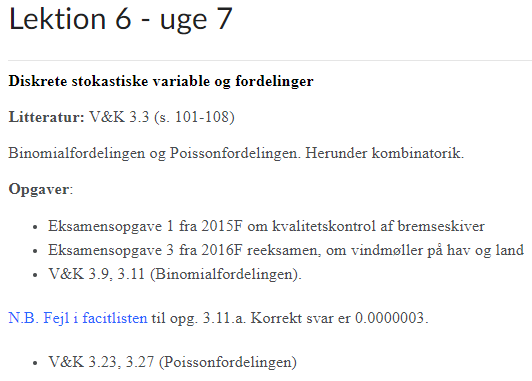

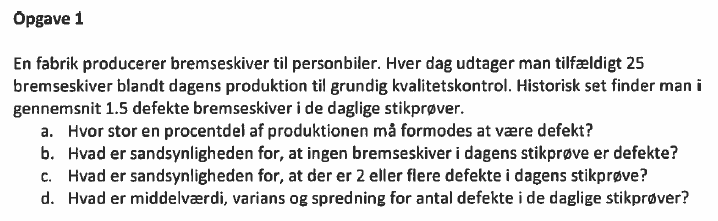

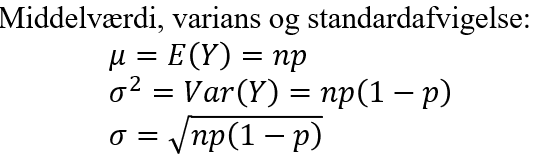

clc; clear;

% Stikprøve på N = 25
N = 25;         % Udtagede bremseskiver
n_defekt = 1.5; % Antal defekte pr dag

% Opgave a
n_defekt_procent = n_defekt/N

n_defekt_procent = 0.0600


% Opgave b - binomialfordelt variabel
antal_defekte = 0;  % Ingen "succeser", hvor succes er defekt
ingen_defekte = binopdf(antal_defekte, N, n_defekt_procent)

ingen_defekte = 0.2129


% Opgave c - P(Y >= 2)
% P(Y >= 2) = 1 - P(Y = 0) - P(Y = 1)
ssh = 1 - ingen_defekte - binopdf(1, N, n_defekt_procent)

ssh = 0.4473


n_defekte_c = 2

n_defekte_c = 2

ssh2 = binocdf(N - n_defekte_c, N, 1 - n_defekt_procent)

ssh2 = 0.4473


% Opgave d - deskriptorer
mu = N * n_defekt_procent

mu = 1.5000

varians = N*n_defekt_procent*(1 - n_defekt_procent)

varians = 1.4100

std = sqrt(varians)

std = 1.1874

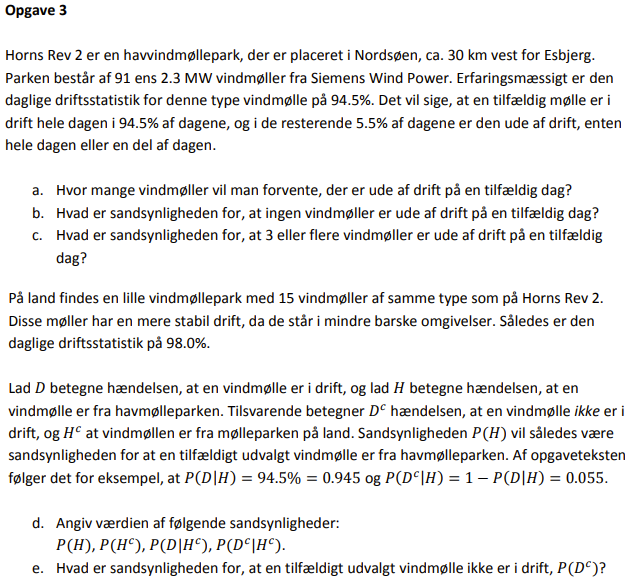

%% a 
% Vi kan antage, at møllernes drift er uafhængig af hinanden, så en mølles 
% nedbrud ikke påvirker de andres. Derfor kan vindmøllernes drift
% modelleres med binomialfordelingen. Det er mest enkelt at lade 'succes'
% betegne, at en mølle er ude af drift. Sandsynligheden for det er 
% p = P(Dc) = 1 - P(D) = 1 - 0.945 = 0.055. 

n = 91          % Antal vindmøller

n = 91

p = 1 - 0.945   % Sandsynligheden for at en vindmølle er ude af drift

p = 0.0550


% Middelværdien for binomialfordelingen (gns. antal succes) er n*p:
gns_itu = n*p

gns_itu = 5.0050

% Der er i gennemsnit 5.005 møller, der er ude af drift på Horns Rev 2


%% b
p_0itu = binopdf(0, n, p)

p_0itu = 0.0058

% Sandsynligheden for at ingen møller er ude af drift er 0.0058, altså 
% meget sjældent 


%% c
% Sandsynligheden for 3 eller flere vindmøller ude af drift svarer til 
% 1 minus sandsynligheden for 0 til 2 er ude af drift. Det kan beregnes 
% med den kumulative fordelingsfunktion (cdf): 
p_mindst3itu = 1 - binocdf(2, n, p)

p_mindst3itu = 0.8828


% Alternativt:
p_mindst3itu_alt = 1 - binopdf(0, n, p) - binopdf(1, n, p) - binopdf(2, n, p)

p_mindst3itu_alt = 0.8828


% Der er mindst 3 møller ude af drift i 88.28% af dagene


%% d
% Oplyst i opgaven:
p_D_givet_H = 0.945

p_D_givet_H = 0.9450

    % P(D|H) = 0.945, da sandsynligheden for at en havmølle er i drift er
    % 94.5%
p_Dc_givet_H = 1 - p_D_givet_H

p_Dc_givet_H = 0.0550

    % P(Dc|H) = 0.055, nemlig sandsynligheden for at en havmølle ikke er i
    % drift

p_H = 91/(91+15)

p_H = 0.8585

    % P(H) = 0.8585, da 91 af ialt 91+15=106 møller er havmøller
p_Hc = 1 - p_H

p_Hc = 0.1415

    % P(Hc) = 0.1415, da de møller, der ikke er havmøller, er landmøller.
    % Det svarer til 15/106
p_D_givet_Hc = 0.980

p_D_givet_Hc = 0.9800

    % P(D|Hc) = 0.980, da landmøllerne er i drift 98.0% af dagene
p_Dc_givet_Hc = 1 - p_D_givet_Hc

p_Dc_givet_Hc = 0.0200

    % P(Dc|Hc) = 0.020, da landmøllerne er ude af drift 2.0% af dagene

    
%% e
p_Dc = p_Dc_givet_H*p_H + p_Dc_givet_Hc*p_Hc

p_Dc = 0.0500

    % Loven om den totale sandsynlighed (Sandsynlighederne for at være ude 
    % af drift i de to parker vægtes med antal møller i parkerne):
    % P(Dc) = P(Dc|H)*P(H) + P(Dc|Hc)*P(Hc) 
    %       = 0.055*0.8585 + 0.020*0.1415 = 0.0500
    % Sandsynligheden for at en mølle er ude af drift er 0.05











